# FFUAV Senior Design - James' Objective Funtion

## Housekeeping

clc; clear; close all;

## Load Data

clc;close all;clear;
load("Battery_chem.mat");
load("All_motor_Prop_combos.mat");
load("all_batteries.mat");

% INPUTS -------------------------------------------------------------
 % Propulsion System
        Num_p_systems = 8; % Number of propulsion Systems
        manufacture_offset = 1.075;
        coaxial_system = 0;
        
        % Battery Type and Sizing
        Bat_Capacity = 40 % amp - Hours

Bat_Capacity = 40

        number_of_cells = 12; 
        Battery_Type = "Li-Hv"; % determines battery chemistery
        if Battery_Type == "Li-Po"
                Battery_chemistery_trial = Battery_chemistry(2,:);
        end
        if Battery_Type == "Li-Hv"
                Battery_chemistery_trial = Battery_chemistry(3,:);
        end
        if Battery_Type == "Li-Ion"
                Battery_chemistery_trial = Battery_chemistry(4,:);
        end
        if Battery_Type == "SS Li-Ion"
                Battery_chemistery_trial = Battery_chemistry(5,:);
        end
        
        Bat_Usage = 0.80;    % max battery allowed to be used
        
        % Aircraft weight estimation - Grams
        airframe = 8359;
        Propulsion = 14202 - 8630;
        Payload = 25 * 453.592 % lbs --> grams

Payload = 1.1340e+04

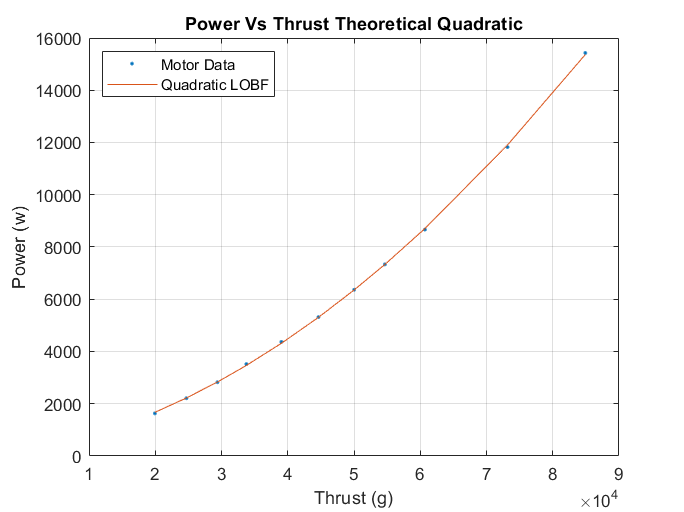

        aircraft_weights = [airframe, Propulsion, Payload,];
        
        % Range and Speed Variables
        Range_conversion_factor = 1.0;
        Target_range_miles = 10.00; % miles
        Estimated_cruise_speed_mph = 25;% mph
        Estimated_aircraft_drag_grams = 7500*25^2/35^2; % grams
        % Minumum Thrust to weight ratio
        TW = 2.0;
        
        if(coaxial_system)
            thrust_multiplier = 0.8;
        else
            Thrust_multiplier = 1;
        end
% OUTPUTS --------------------------------------------------------------

% Define looping variables
best = [1, 0];
old = [0, 0];
% Loop start
for i = 10

        % Battery Specifications
        low_battery_voltage = Battery_chemistery_trial{7};
        nom_battery_voltage = Battery_chemistery_trial{11};
        Battery_energy_density = Battery_chemistery_trial{3};
        Battery_weight_est = Bat_Capacity * nom_battery_voltage / Battery_energy_density;
        Battery_C_rating = Battery_chemistery_trial{2};
        
        % quadratic Power Vs Thrust
        Thrust_newtons = nonzeros(rmmissing(allMPCs(i).Thrust_N(:,2)));
        Thrust_grams = Thrust_newtons * 101.971621297793; % convert to grams
        Power_Watts = nonzeros(rmmissing((allMPCs(i).Power_W(:,2))));
        Total_thrust_newtons = Thrust_multiplier * Thrust_newtons * Num_p_systems;
        Total_thrust_grams = Total_thrust_newtons * 101.971621297793; %convert to grams
        Total_power_watts = Num_p_systems * Power_Watts * manufacture_offset;
        %plotting
        figure(1)
        quad_coefs = polyfit(Total_thrust_grams,Total_power_watts,2);
        power_fit = polyval(quad_coefs,Total_thrust_grams);
        plot(Total_thrust_grams,Total_power_watts,'.')
        hold on
        plot(Total_thrust_grams,power_fit)
        title("Power Vs Thrust Theoretical Quadratic")
        xlabel("Thrust (g)")
        ylabel("Power (w)")
        legend("Motor Data", "Quadratic LOBF",'Location','northwest')
        grid on
        
        %Aircraft Weight Estimates - grams
        Aircraft_empty_weight_w_payload_g = sum(aircraft_weights);
        Aircraft_all_up_weight_g = Aircraft_empty_weight_w_payload_g + Battery_weight_est;
        Aircraft_weight_w_drag_g = Aircraft_all_up_weight_g + Estimated_aircraft_drag_grams;
        
        % Power Consumption Estimates
        Hover_power_consumption_watts = quad_coefs(1)*Aircraft_all_up_weight_g^2 + quad_coefs(2)*Aircraft_all_up_weight_g + quad_coefs(3);
        Cruise_power_consumption_watts = quad_coefs(1)*Aircraft_weight_w_drag_g^2 + quad_coefs(2)*Aircraft_weight_w_drag_g + quad_coefs(3);
        Cruise_power_consumption_C = Cruise_power_consumption_watts / (nom_battery_voltage*Bat_Capacity);
        
        % FLight Time and Range Estimation
        Hover_flight_time_minutes = Bat_Capacity * nom_battery_voltage * Bat_Usage / Hover_power_consumption_watts * 60;
        Cruise_flight_time_minutes = Bat_Capacity * nom_battery_voltage * Bat_Usage / Cruise_power_consumption_watts * 60;
        Direct_line_range = Cruise_flight_time_minutes / 60 * Estimated_cruise_speed_mph;
        
        % Battery Capacity range Calculations
        Max_Thrust_grams = max(Total_thrust_grams);
        Battery_testing_voltage = mean(nonzeros(rmmissing(allMPCs(i).Voltage(2,:))));
        Max_thrust_dead_battery = (low_battery_voltage/Battery_testing_voltage)^1.5 * Max_Thrust_grams;
        
        % Thrust to weight ratio at dead battery
        Thrust_to_weight_ratio_dead_battery = Max_thrust_dead_battery / Aircraft_all_up_weight_g;
        
        Max_taekoff_weight_grams = Max_thrust_dead_battery/TW;
        Max_battery_weight_grams = Max_taekoff_weight_grams - Aircraft_empty_weight_w_payload_g;
        Max_battery_capacity_Ah = Max_battery_weight_grams * Battery_energy_density / nom_battery_voltage;
        
        if Thrust_to_weight_ratio_dead_battery >= TW
            % Thrust to weight constraint passed
            if Cruise_power_consumption_C < (0.66 * Battery_C_rating)
                % Cruise Power constraint passed
                if Direct_line_range > old(2)
                    % store best
                    best = [i, Direct_line_range, Aircraft_all_up_weight_g];
                    old = best;
                end
            end
        end
end

## Experimental Data Processing Test Days

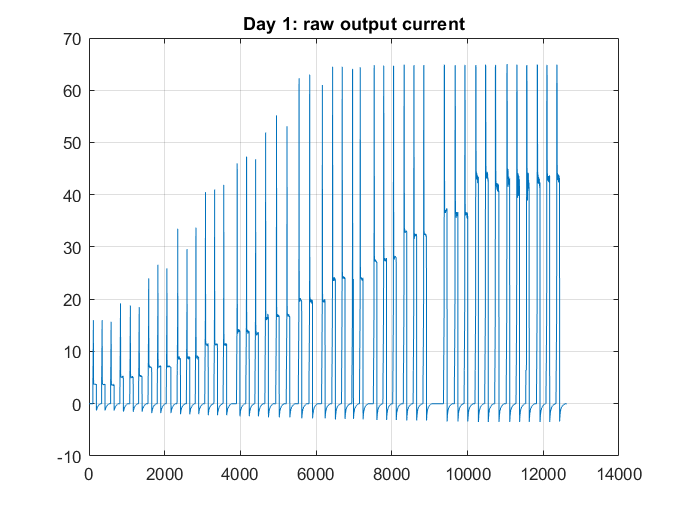

% Start of program
% load data from CSVs
clear; clc; close all;

load('Propulsion_Test_Day_1.mat')

%% plot raw data
packet_num = [Datalink_Day1_set1; Datalink_Day1_set2; Datalink_Day1_set3; Datalink_Day1_set4];
% Plotting
figure(1)
plot(packet_num.PackageNumber, packet_num.OutputCurrent)
grid on
title('Day 1: raw output current')

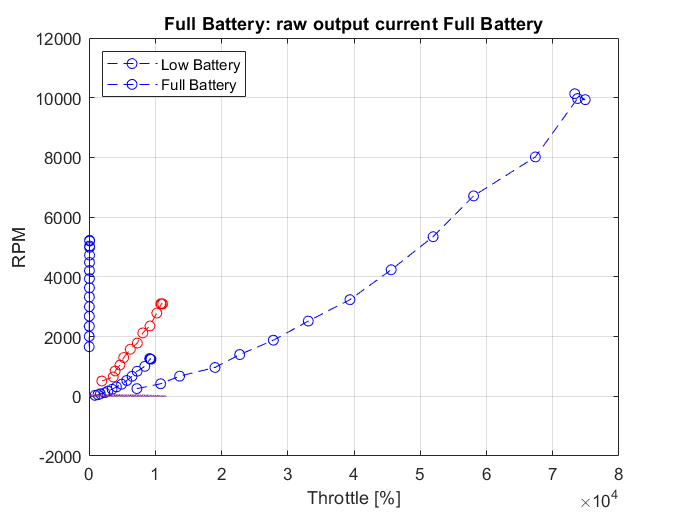


% Initialize Variables
i = 0;
k = 0;
Trial_ID = 0;
save = false;
% Loop
while i < height(packet_num)
    i = i+1;
    % Check if current value is reading
    if(packet_num.OutputCurrent(i) > 0)
        save = true;
        Trial_ID = Trial_ID + 1;
    end
    % read all current values until it cannot
    while(save)
        k = k + 1;
        Current(k,Trial_ID) = packet_num.InputCurrent(i);
        Voltage(k,Trial_ID) = packet_num.Voltage(i);
        outputPower(k,Trial_ID) = Current(k,Trial_ID)* Voltage(k,Trial_ID);
        RPM(k,Trial_ID) = packet_num.RPM(i);
        i = i + 1;
        % look for end of trial
        if(packet_num.OutputCurrent(i) <= 0)
            save = false;
            k = 0;
        end
    end
end

% POWER: Generate Datapoint from each trial
for i = 1:width(outputPower)
    trial = nonzeros(outputPower(:,i));
    L = length(trial);
    trial(round(L*0.75):end) = [];
    trial(1:round(L*0.25)) = [];
    Output_Power_points(i) = mean(trial);
end
% RPM: Generate Datapoint from each trial
for i = 1:width(RPM)
    trial = nonzeros(RPM(:,i));
    L = length(trial);
    trial(round(L*0.75):end) = [];
    trial(1:round(L*0.25)) = [];
    RPM_points(i) = mean(trial);
end

%specific tuning (remove dud runs, fix duplicates, etc)
Output_Power_points(27) = [];  % remove trial 27 as it was a dud trial
RPM_points(27) = [];
% Average each throttle % into one point
i = 1;
k = 0;
while i <= length(Output_Power_points)
    k = k+1;
    Average_power_at_each_throttle(k) = mean(Output_Power_points(i:i+2));
    Average_RPM_at_each_throttle(k) = mean(RPM_points(i:i+2));
    i = i+3;
end

%% Thrust
Thrust = table2array(LoadCellTest1Thrust(4,2:16));

% Throttle Percentage
for i = 1:length(Thrust)
    throttle_percent(i) = 30 + (i-1)*5;
end

% Plotting
figure(3)
plot(Thrust*453.5928, Average_power_at_each_throttle,'b--o') % convert thrust to lbs --> grams, 
grid on 
hold on
xlabel('Thrust [g]')
ylabel('Power [W]')
title('Single Motor: Experimental Power vs Thrust')

figure(4)
plot(Thrust*453.5928*8,Average_power_at_each_throttle*8,'b--o')
grid on
hold on
xlabel('Total thrust [g]')
ylabel('Total Power [watts]')
title('Full System: Experiementally Projected P vs T')

figure(5)
plot(throttle_percent,Average_RPM_at_each_throttle,'b--o')
grid on
hold on
xlabel('Throttle [%]')
ylabel('RPM')
title('Throttle % to RPM')


%% Propulsion Test Day #2: Full Batteries
% load data from CSVs
clear;
load('Test_Day_2.mat')

%% plot raw data
packet_num = [Data1; Data2; Data3; Data4];
figure(6)
plot(packet_num.PackageNumber, packet_num.OutputCurrent)
grid on
title('Full Battery: raw output current Full Battery')

% Initialize Variables
i = 0;
k = 0;
j = 0;
Trial_ID = 0;
save = false;
% Loop
while i < height(packet_num)
    i = i+1;
    % Check if current value is reading
    if(packet_num.OutputCurrent(i) > 0)
        save = true;
        Trial_ID = Trial_ID + 1;
    end
    % read all current values until it cannot
    while(save)
        k = k + 1;
        Current(k,Trial_ID) = packet_num.OutputCurrent(i);
        outputVoltage(k,Trial_ID) = packet_num.Voltage(i);
        outputPower(k,Trial_ID) = Current(k,Trial_ID)*outputVoltage(k,Trial_ID);
        RPM(k,Trial_ID) = packet_num.RPM(i);
        i = i + 1;
        % look for end of trial
        if(packet_num.OutputCurrent(i) <= 0)
            save = false;
            k = 0;
        end
    end
end
% POWER: Generate Datapoint from each trial
for i = 1:width(outputPower)
    trial = nonzeros(outputPower(:,i));
    L = length(trial);
    trial(round(L*0.75:end)) = [];
    trial(1:round(L*0.25)) = [];
    Output_Power_points(i) = mean(trial);
end
% RPM: Generate Datapoint from each trial
for i = 1:width(RPM)
    trial = nonzeros(RPM(:,i));
    L = length(trial);
    trial(round(L*0.75:end)) = [];
    trial(1:round(L*0.25)) = [];
    RPM_points(i) = mean(trial);
end
% manual Tuning - Removing Outliers/Dud Runs
Output_Power_points(:,[1,2,9,15,22,23,34]) = [];
RPM_points(:,[1,2,9,15,22,23,34]) = [];

% Average each throttle % into one point
i = 1;
k = 0;
while i <= length(Output_Power_points)
    k = k+1;
    Average_power_at_each_throttle(k) = mean(Output_Power_points(i:i+2));
    Average_RPM_at_each_throttle(k) = mean(RPM_points(i:i+2));
    i = i+3;
end

%% Thrust
Thrust = table2array(Avg_Load);
% Throttle Percentage
for i = 1:length(Thrust)
    throttle_percent(i) = 40 + (i-1)*5;
end
Average_RPM_at_each_throttle = flip(Average_RPM_at_each_throttle);
Average_power_at_each_throttle = flip(Average_power_at_each_throttle);
Thrust = flip(Thrust);

% Plotting
figure(3)
plot(Thrust*453.5928, Average_power_at_each_throttle,'r--o') % convert thrust to lbs --> grams, 
legend('Low Battery','Full Battery','Location','northwest')

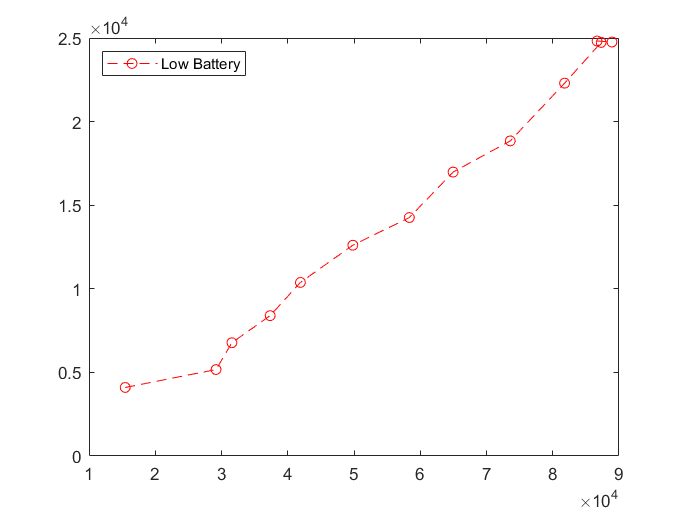

figure(4)
plot(Thrust*453.5928*8,Average_power_at_each_throttle*8,'r--o')
legend('Low Battery','Full Battery','Location','northwest')

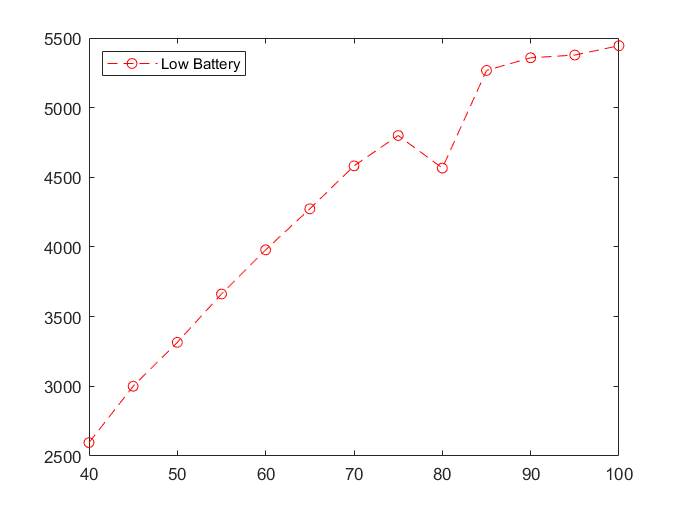

figure(5)
plot(throttle_percent,Average_RPM_at_each_throttle,'r--o')
legend('Low Battery','Full Battery','Location','northwest')

## Test day 3

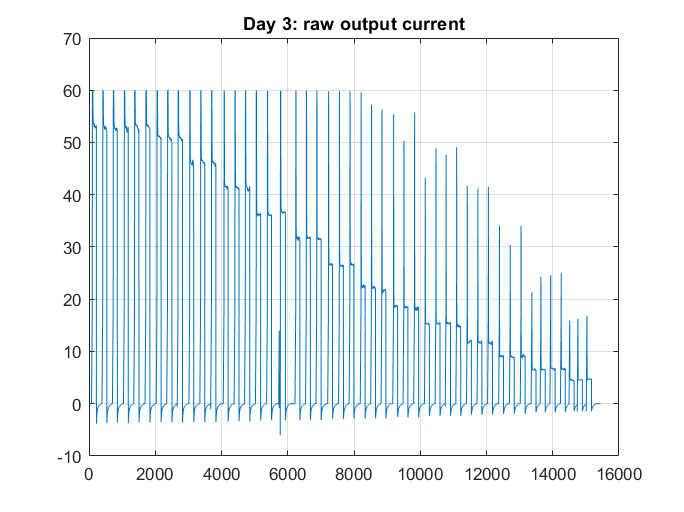

% Start of program
% load data from CSVs
clear; clc; close all;

load('Test_Day_3.mat')

%% plot raw data
packets = [FullBat2Set1; FullBat2Set2; FullBat2Set3; FullBat2Set4];
% Plotting
figure(1)
plot(packets.PackageNumber, packets.OutputCurrent)
grid on
title('Day 3: raw output current')

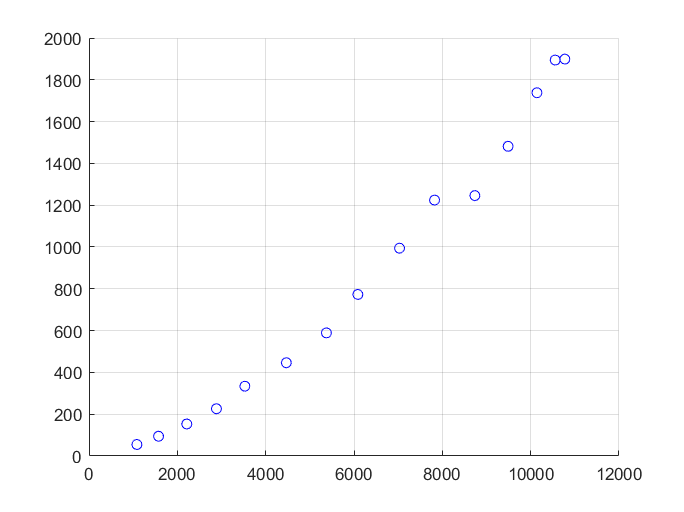


% Initialize Variables
i = 0;
k = 0;
Trial_ID = 0;
save = false;
% Loop
while i < height(packets)
    i = i+1;
    % Check if current value is reading
    if(packets.InputCurrent(i) > 0)
        save = true;
        Trial_ID = Trial_ID + 1;
    end
    % read all current values until it cannot
    while(save)
        k = k + 1;
        Current(k,Trial_ID) = packets.InputCurrent(i);
        Voltage(k,Trial_ID) = packets.Voltage(i);
        outputPower(k,Trial_ID) = Current(k,Trial_ID)* Voltage(k,Trial_ID);
        RPM(k,Trial_ID) = packets.RPM(i);
        i = i + 1;
        % look for end of trial
        if(packets.InputCurrent(i) <= 0)
            save = false;
            k = 0;
        end
    end
end

% POWER: Generate Datapoint from each trial
for i = 1:width(outputPower)
    trial = nonzeros(outputPower(:,i));
    L = length(trial);
    trial(round(L*0.75):end) = [];
    trial(1:round(L*0.25)) = [];
    Output_Power_points(i) = mean(trial);
 end
% RPM: Generate Datapoint from each trial
for i = 1:width(RPM)
    trial = nonzeros(RPM(:,i));
    L = length(trial);
    trial(round(L*0.75):end) = [];
    trial(1:round(L*0.25)) = [];
    RPM_points(i) = mean(trial);
end

%specific tuning (remove dud runs, fix duplicates, etc)
 Output_Power_points([18,35,45]) = []; 
 RPM_points([18,35,45]) = [];
% Average each throttle % into one point
i = 1;
k = 0;
while i <= length(Output_Power_points)
    k = k+1;
    Average_power_at_each_throttle(k) = mean(Output_Power_points(i:i+2));
    Average_RPM_at_each_throttle(k) = mean(RPM_points(i:i+2));
    i = i+3;
end

%% Thrust
Thrust = table2array(TestDay3thrust(:,4));

% Throttle Percentage
for i = 1:length(Thrust)
    throttle_percent(i) = 30 + (i-1)*5;
end
throttle_percent = flip(throttle_percent);

% Plotting
figure(1)
scatter(Thrust*453.5928, Average_power_at_each_throttle,'b') % convert thrust to lbs --> grams, 
grid on 
hold on

quad_coefs_exp = polyfit(Thrust*453.5928, Average_power_at_each_throttle,2);
power_fit_exp = polyval(quad_coefs_exp, Thrust*453.5928);
plot(Total_thrust_grams,power_fit_exp)

Unrecognized function or variable 'Total_thrust_grams'.


figure(3)
plot(Thrust*453.5928*8,Average_power_at_each_throttle*8,'b--o')
grid on
hold on
xlabel('Total thrust [g]')
ylabel('Total Power [watts]')
title('Full System: Experiementally Projected P vs T')

figure(4)
plot(throttle_percent,Average_RPM_at_each_throttle,'b--o')
grid on
hold on
xlabel('Throttle [%]')
ylabel('RPM')
title('Throttle % to RPM')


